Digital Signal Processing Lab (EE-384L)

# Lab 6:   **Tasks**

### Reg. No. :   **2016-EE-189**

## Task 1

**Statement:**

Any arbitrary complex-valued sequence $x\left\lbrack n\right\rbrack$ can be decomposed into $x\left\lbrack n\right\rbrack =x_e \left\lbrack n\right\rbrack +x_o \left\lbrack n\right\rbrack$, where $x_e \left\lbrack n\right\rbrack$ is the conjugate-symmetric part and $x_o \left\lbrack n\right\rbrack$ is the conjugate-antisymmetric part of $x\left\lbrack n\right\rbrack$, and they're given by, 

$x_e \left\lbrack n\right\rbrack =\frac{1}{2}\left(x\left\lbrack n\right\rbrack +x^* \left\lbrack -n\right\rbrack \right)$          and          $x_o \left\lbrack n\right\rbrack =\frac{1}{2}\left(x\left\lbrack n\right\rbrack -x^* \left\lbrack -n\right\rbrack \right)$

**Question (1):**

Modify the $\textrm{evenodd}\left(\right)$ function so that it accepts an arbitrary sequence and decomposes it into its conjugate-symmetric ($\textrm{CA}$) and conjugate-antisymmetric ($\textrm{CAS}$) components.

**Answer (1):**

The code of the modified $\textrm{evenodd}\left(\right)$ function, that decomposes given sequence into its $\textrm{CS}$ and $\textrm{CAS}$ components, is given below.

% <function>
% signal decomposition into conjugate-symmetric (xe[n]) and 
% conjugate-antisymmetric (xo[n]) parts
%
% <syntax>
% [xe, xo, m] = evenodd(x, n)
%
% <I/O>
% x = input sequence x[n] (over DT points 'n')
% xe = conjugate-symmetric (CS) part of x[n], given by xe[n] = (x[n]+x*[-n])/2
% xo = conjugate-antisymmetric (CAS) part of x[n], given by xo[n] = (x[n]-x*[-n])/2

function [xe, xo, m] = evenodd(x, n)

    % obtain the time-reversed version of x[n] i.e. x[-n]
    [xflp, nflp] =  sigfold(x, n);

    % obtain the conjugate x*[-n]
    xflpc =  conj(xflp);

    % conjugate-symmetric part of x[n], xe[n] = (x[n]+x*[-n])/2
    [xe, m] = sigadd(x, n, xflpc, nflp);
    xe = 0.5*xe;
    
    % conjugate-antisymmetric part of x[n], xo[n] = (x[n]-x*[-n])/2
    [xo, m] = sigadd(x, n, -xflpc, nflp);
    xo = 0.5*xo;

end

**Question (2):**

Decompose the sequence $x\left\lbrack n\right\rbrack =10\;\exp \left(\left\lbrack -0\ldotp 1+\textrm{j0}\ldotp 2\pi \right\rbrack n\right)$, $0\le n\le 10$ into its conjugate-symmetric ($\textrm{CS}$) and conjugate-antisymmetric ($\textrm{CAS}$) components. Plot their real and imaginary parts to verify the decomposition.

**Answer (2):**

Following MATLAB code uses the above $\textrm{evenodd}\left(\right)$ function to decompose given $x\left\lbrack n\right\rbrack$ into its $\textrm{CS}$ and $\textrm{CAS}$ parts.

% define the sequence x[n]
n = 0:10;
x = 10*exp((-0.1 + 1i*0.2*pi)*n);

% obtain CS (xe[n]) and CAS (xo[n]) parts of x[n]
[xe, xo, m] = evenodd(x, n);

% plot real and imaginary parts of CS & CAS decomposition
fig = figure; set(fig,'Units','normalized','Position',[0 0 1 1.6]);

% plot real and imaginary parts of CS xe[n]
subplot(2, 2, 1);
stem(m, real(xe), 'filled', 'MarkerSize', 3);
xlabel('n'); ylabel('Real\{ x_e[n] \}');
title({'Real Part of CS x_e[n]';''});
subplot(2, 2, 2);
stem(m, imag(xe), 'filled', 'MarkerSize', 3);
xlabel('n'); ylabel('Imag\{ x_e[n] \}');
title({'Imaginary Part of CS x_e[n]';''});

% plot real and imaginary parts of CAS xo[n]
subplot(2, 2, 3);
stem(m, real(xo), 'filled', 'MarkerSize', 3);
xlabel('n'); ylabel('Real\{ x_o[n] \}');
title({'Real Part of CAS x_o[n]';''});
subplot(2, 2, 4);
stem(m, imag(xo), 'filled', 'MarkerSize', 3);
xlabel('n'); ylabel('Imag\{ x_o[n] \}');
title({'Imaginary Part of CAS x_o[n]';''});

*Next task starts from the next page.*

## Task 2

**Statement:**

The operation of *signal dilation* (or *decimation* or *down-sampling*) is defined by $y\left\lbrack n\right\rbrack =x\left\lbrack \textrm{nM}\right\rbrack$, in which the sequence $x\left\lbrack n\right\rbrack$ is down-sampled by an integer factor $M$.

**Question (1):**

Develop a MATLAB function $\textrm{function}\;\left\lbrack y,\;m\right\rbrack =\textrm{dnsample}\left(x,\;n,\;M\right)$ to implement the down-sampling operation.

**Answer (1):**

Code for $\textrm{dnsample}\left(\right)$, that downsamples a given sequence $x\left\lbrack n\right\rbrack$ by a factor $M$ to obtain $y\left\lbrack m\right\rbrack$, is given below.

% <function>
% downsamples sequence x[n] by a factor M to obtain y[n] = x[nM],
% returns empty vectors if no samples exist in resultant range
%
% <syntax>
% [y, m] = dnsample(x, n, M)
%
% <I/O>
% x = input sequence x[n],  M = decimation factor,  y = output (dilated) sequence = x[nM]

function [y, m] = dnsample(x, n, M)
    
    % M must be a non-zero positive number (int)
    if (M <= 0); error('M must be a non-zero positive number'); end; M = round(M, 0);
    
    % mod(a, b): nonzero results are always negative if the divisor is negative
    diff = mod(n(1), M);
    
    % keeping y[0]=x[0.M]=x[0], beginning m value should be
    % and always positive if the divisor is positive
    if diff == 0
        m_b_inx = 1;                        % starts at same value as in n
    else 
        m_b = n(1) + M - mod(n(1), M);
        m_b_inx = find(n == m_b);           % index in n of beginning m value
        if ~isempty(m_b_inx) m_b_inx = m_b_inx(1); end;
    end
    
    % decimate x[n] to get y[n]=x[nM]
    m = n(m_b_inx:M:end)/M;
    y = x(m_b_inx:M:end);
    
end

**Question (2):**

Generate $x\left\lbrack n\right\rbrack =\sin \left(0\ldotp 125\pi n\right)$, $-50\le n\le 50$. Decimate $x\left\lbrack n\right\rbrack$ by a factor of $4$ to generate $y\left\lbrack n\right\rbrack$. Plot both $x\left\lbrack n\right\rbrack$ and $y\left\lbrack n\right\rbrack$, and comment on the results.

**Answer (2):**

Following MATLAB code uses the above $\textrm{dnsample}\left(\right)$ function to decimate given $x\left\lbrack n\right\rbrack$ by a factor of $4$.

% define sequence x[n]
n = -50:50;
x = sin(0.125*pi*n);

% decimate x[n] by M=4
M = 4;
[y, m] = dnsample(x, n, M);

% plot sequences x[n] and y[n]
% function called below is provided at the end of code section in Answer (3)
plotXY_t2(x, n, y, m, M, 'sin(0.125\pin)');

Since the decimation factor here is $M=4$, so starting from $n=0$, in either direction, only the fourth sample is kept, and the 3 in between are dropped. The sample value at $n=5$ in $y\left\lbrack n\right\rbrack$ is the one at $n=5\left(4\right)=20$ in $x\left\lbrack n\right\rbrack$, and the value at $n=10$ in $y\left\lbrack n\right\rbrack$ is the one at $n=10\left(4\right)=40$ in $x\left\lbrack n\right\rbrack$, and so on. This means that for the same sample (digital) frequency, reconstrcuted $y\left(t\right)$ could have a higher (analog) frequency than $x\left(t\right)$.

Here, since $x\left\lbrack n\right\rbrack$ has a single constant sinusoidal frequency, and the oscillation is preserved after decimation, in $y\left\lbrack n\right\rbrack$, so the frequency content (DTFT) of the signal is preserved, although scaled, after this decimation by $M=4$. This means that the original signal (say $x\left(t\right)$) is still recoverable using the decimated $y\left\lbrack n\right\rbrack$, by using a new suitable sample-rate.

**Question (3):**

Repeat Q3 using $x\left\lbrack n\right\rbrack =\sin \left(0\ldotp 5\pi n\right)$, $-50\le n\le 50$. Qualitatively discuss the effect of down-sampling on signals.

**Answer (3):**

Following MATLAB code uses the $\textrm{dnsample}\left(\right)$ function (from Q1) to decimate given $x\left\lbrack n\right\rbrack$ by a factor of $4$.

% define sequence x[n]
n = -50:50;
x = sin(0.5*pi*n);

% decimate x[n] by M=4
M = 4;
[y, m] = dnsample(x, n, M);

% plot sequences x[n] and y[n] (using function given below)
plotXY_t2(x, n, y, m, M, 'sin(0.5\pin)');

% <function> to plot x[n] (original) and y[n] (decimated) in 2x1 subplot
% ------------
function plotXY_t2(x, n, y, m, M, x_eq)
    fig = figure; set(fig,'Units','normalized','Position',[0 0 1.4 1]);
    subplot(2, 1, 1);
    stem(n, x, 'filled', 'MarkerSize', 5);          % plot x[n]
    xlabel('n'); ylabel('x[n]'); xlim([min(n) max(n)]);
    title({['x[n] = ', x_eq,' (original sequence)'];''}, 'FontSize', 16);
    subplot(2, 1, 2);
    stem(m, y, 'filled', 'MarkerSize', 5);          % plot y[n]
    xlabel('n'); ylabel('y[n]'); xlim([min(n)/4 max(n)/4]); ylim([min(x) max(x)]);
    title(['y[n] = x[nM] = x[', num2str(M), 'n] (decimated sequence)'], 'FontSize', 16);
end

**Comment on the effect of down-sampling on signals:**

Now (in Q3), since the oscillation is not preserved after decimation, in $y\left\lbrack n\right\rbrack$, so the original signal can no longer be recovered using the decimated $y\left\lbrack n\right\rbrack$. 

For a signal $x\left(t\right)$ to be entirely recoverable from its sampled version $x\left\lbrack n\right\rbrack$, the sampling frequency $\Omega_S =2\pi F_S$ must be twice (or more than) the maximum frequency (say $\Omega_N$) in the time-domain signal $x\left(t\right)$, that is,


$$\Omega_S \;\ge \;2{\;\Omega }_N$$


so that all the frequencies (say $-\Omega_N$ to $+\Omega_N$) in $x\left(t\right)$ are properly mapped to the DTFT range $\omega =-\pi$ to $+\pi$ in the DT version (if $\Omega_S =2{\;\Omega }_N$), and any aliasing/overlapping is avoided.

Decimation by a factor of $M=4$ essentially means that, in context of the original signal $x\left(t\right)$, the sampling-rate to obtain its (decimated) DT version has by reduced by a factor of $M=4$. So if $M$ is such that, 


$$\frac{\Omega_S }{M}\;<\;2{\;\Omega }_N$$


where $\Omega_S /M$ is the effective sample-rate for $y\left\lbrack n\right\rbrack$, then the original CT signal will not be entirely recoverable from the decimated DT signal, which we can infer is the case here (in Q3).

In cases where the Nyquist limit is still satisfied after decimation, the decimated signal is quite desirable for the speed-ups it provides in computation, compared to the greater number of unnecesarry computations in case of the undecimated sequence; as both result in the same output (CT) signal upon reconstruction.

*Next task starts from the next page.*

## Task 3

**Statement:**

Consider the following finite-duration sequences, called *windows:*


$$\begin{array}{l}
\textrm{Rectangular}:{\;\;\;\;\;\;R}_M \left\lbrack n\right\rbrack \;=\;1\;\textrm{for}\;0\le n<M,\;\textrm{and}\;0\;\textrm{otherwise}\\
\textrm{Hanning}:{\;\;\;\;\;\;\;\;\;\;\;\;\;C}_M \left\lbrack n\right\rbrack \;=\;0\ldotp 5\left\lbrack 1-\cos \left(\frac{2\pi n}{M-1}\right)\right\rbrack {\;R}_M \left\lbrack n\right\rbrack \\
\textrm{Triangular}:\;\;\;\;\;\;\;\;{\;T}_M \left\lbrack n\right\rbrack \;=\left\lbrack 1-\frac{|M-1-2n|}{M-1}\right\rbrack \;R_M \left\lbrack n\right\rbrack \\
\textrm{Hamming}:\;\;\;\;\;\;\;\;\;H_M \left\lbrack n\right\rbrack \;=\left\lbrack 0\ldotp 54-0\ldotp 46\;\cos \left(\frac{2\pi n}{M-1}\right)\right\rbrack \;R_M \left\lbrack n\right\rbrack 
\end{array}$$


For each of these windows, determine their DTFTs for $M=10,\;25,\;50,\;101$. Scale transform values so that the maximum value is equal to $1$. Plot the magnitude of the normalized DTFT over $-\pi \le \omega \le \pi$. 

Study these plots and comment on their behavior as a function of $M$.

**Code (with results):**

The code for computing & plotting the normalized DTFT magnitudes for each $M$, for all the given window-sequences, is given below.

M = [10 25 50 101];                     % values of M for which to compute window DTFT
w = -pi:0.01:pi;                        % frequency vector for computing DTFTs of windows
    
% >>> window 1 <<< Rectangular: RM[n]

RM = cell(length(M), 1);                % cell-array to store RM[n] window sequences 
                                        % for each M value
RMw = cell(length(M), 1);               % cell-array to store the DTFTs for each M value

for i = 1:length(M)

    % define RM[n] = 1 for 0≤n<M, 0 otherwise
    n = 0:(M(i)-1);
    RM{i} = ones(1, length(n));
    
    % compute the DTFT of RM[n] i.e. RM(w), using matrix-mult. method
    RMw{i} = RM{i} * exp(-1i * n' * w);
    
end

% plot DTFT magnitude |RM(w)| for each M (using function defined at end of this script)
plot4DTFTmag_t3(RMw, w, M, 'R', 'Rectangular Window');
% >>> window 2 <<< Hanning: CM[n]

CMw = cell(length(M), 1);               % cell-array to store the DTFTs for each M value

for i = 1:length(M)

    % define CM[n] = 0.5( 1 - cos(2πn/(M-1)) ).RM[n]   (for 0≤n<M)
    n = 0:(M(i)-1);
    CM = 0.5*(1 - cos(2*pi*n/(M(i)-1))).*RM{i};
    
    % compute the DTFT of CM[n] i.e. CM(w), using matrix-mult. method
    CMw{i} = CM * exp(-1i * n' * w);
    
end

% plot DTFT magnitude |CM(w)| for each M (using function defined at end of this script)
plot4DTFTmag_t3(CMw, w, M, 'C', 'Hanning Window');
% >>> window 3 <<< Triangular: TM[n]

TMw = cell(length(M), 1);               % cell-array to store the DTFTs for each M value

for i = 1:length(M)

    % define TM[n] = (1 - |M-1-2n|/(M-1)).RM[n]   (for 0≤n<M)
    n = 0:(M(i)-1);
    TM = (1 - abs(M(i)-1-2*n)/(M(i)-1)).*RM{i};
    
    % compute the DTFT of TM[n] i.e. TM(w), using matrix-mult. method
    TMw{i} = TM * exp(-1i * n' * w);
    
end

% plot DTFT magnitude |TM(w)| for each M (using function defined at end of this script)
plot4DTFTmag_t3(TMw, w, M, 'T', 'Triangular Window');
% >>> window 4 <<< Hamming: HM[n]

HMw = cell(length(M), 1);               % cell-array to store the DTFTs for each M value

for i = 1:length(M)

    % define HM[n] = ( 0.54 - 0.46cos(2πn/(M-1)) ).RM[n]   (for 0≤n<M)
    n = 0:(M(i)-1);
    HM = (0.54 - 0.46*cos(2*pi*n/(M(i)-1))).*RM{i};
    
    % compute the DTFT of HM[n] i.e. HM(w), using matrix-mult. method
    HMw{i} = HM * exp(-1i * n' * w);
    
end

% plot DTFT magnitude |HM(w)| for each M (using function defined at end of this script)
plot4DTFTmag_t3(HMw, w, M, 'H', 'Hamming Window');
% <function> to plot DTFTs (magintude, normalized) of any window for 4 M values
% ------------
function plot4DTFTmag_t3(dtfts, w, M, wind, windn)
    fig = figure; set(fig,'Units','normalized','Position',[0 0 1 1.6]);
    sgtitle([wind_name, '  ', wind, '_M[n]']);
    for i = 1:4
        XMw_mag = abs(dtfts{i});                % get the magnitude of XM(w)
        XMw_mag_norm = XMw_mag/max(XMw_mag);    % normalize mag. so that max value = 1
        
        subplot(2, 2, i);
        plot(w, XMw_mag_norm);                  % plot normalized magnitude of DTFT XM(w)
        xlabel('w   (radians/sample)'); ylabel(['|', wind, '_M' ,'(e^{jw})|']);
        ttl = {['[M = ', num2str(M(i)), '] Magnitude of ', wind, '_M(e^{jw}) vs w'];''};
        if i > 2;  ttl = [{''}; ttl]; end; title(ttl);
        setDTFTradialAxis(1);
    end
end

**Comment on  behaviour of window DTFTs for different **$\mathit{\mathbf{M}}$ **values:**

The windows all show low-pass behaviour, with some much-smaller lobes on each side of the central lobe. For each of the windows, as $M$ is increased, the width of the central lobe decreases, so if these windows are used as filters, then by increasing $M$, the cutoff frequency can be decreased. Furthermore, the cutoff is also made sharper by increasing $M$. Hence, by using a large $M$, and adding a shift to the window spectrum, a very narrow-pass filter can be made to allow only a very-small range of frequencies through the system.

The quantity and magnitude of the smaller side-lobes varies across the different windows. The rectangular window $R_M \left\lbrack n\right\rbrack$ has most prominent and most number of these side-lobes, the triangular window $T_M \left\lbrack n\right\rbrack$ has lesser, while the hanning window $C_M \left\lbrack n\right\rbrack$ has even less prominent side-lobes. The hamming window $H_M \left\lbrack n\right\rbrack$ has nearly insignificant side-lobes. The windows approach the behaviour of function $\delta \left(f\right)$ in frequency-domain for a very large $M$ value, which can be used to single out particular frequencies, by adding some frequency-shift.

## Task 4

**Statement:**

Show that the real part of $X\left(e^{j\omega } \right)$ of a sinusoidal pulse $x\left\lbrack n\right\rbrack =\cos \left(\omega_0 \;n\right){\;R}_M \left\lbrack n\right\rbrack$, where $R_M \left\lbrack n\right\rbrack$ is the rectangular pulse ($R_M \left\lbrack n\right\rbrack \;=\;1\;\textrm{for}\;0\le n<M,\;\textrm{and}\;0\;\textrm{otherwise}$), is given by,


$$\begin{array}{l}
X_R \left(e^{j\omega } \right)\;\;=\;\;\frac{1}{2}\;\cos \left\lbrace \frac{\left(\omega -\omega_0 \right)\left(M-1\right)}{2}\right\rbrace \;\frac{\sin \left\lbrace \left(\omega -\omega_0 \right)M/2\right\rbrace }{\;\sin \left\lbrace \left(\omega -\omega_0 \right)/2\right\rbrace }\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\;\frac{1}{2}\;\cos \left\lbrace \frac{\left(\omega +\omega_0 \right)\left(M-1\right)}{2}\right\rbrace \;\frac{\sin \left\lbrace \left\lbrack \omega -\left(2\pi -\omega_0 \right)\right\rbrack M/2\right\rbrace }{\;\sin \left\lbrace \left\lbrack \omega -\left(2\pi -\omega_0 \right)\right\rbrack /2\right\rbrace }
\end{array}$$


Compute and plot $X_R \left(e^{j\omega } \right)$ over $\left\lbrack -\pi ,\;\pi \right\rbrack$ for $\omega_0 =\pi /2$ and $M=5,\;15,\;25,\;100$. Comment on your results.

**Proof for the equation of **${\mathit{\mathbf{X}}}_{\mathit{\mathbf{R}}} \left({\mathit{\mathbf{e}}}^{\mathit{\mathbf{j}}\omega } \right)$** (paperwork):**

The work done on paper, deriving/showing that the equation for $X_R \left(e^{j\omega } \right)$ (for given $x\left\lbrack n\right\rbrack =\cos \left(\omega_0 \;n\right){\;R}_M \left\lbrack n\right\rbrack$) is the one shown in the Task Statement above, starts from the next page.

*The work done on paper starts from the next page.*

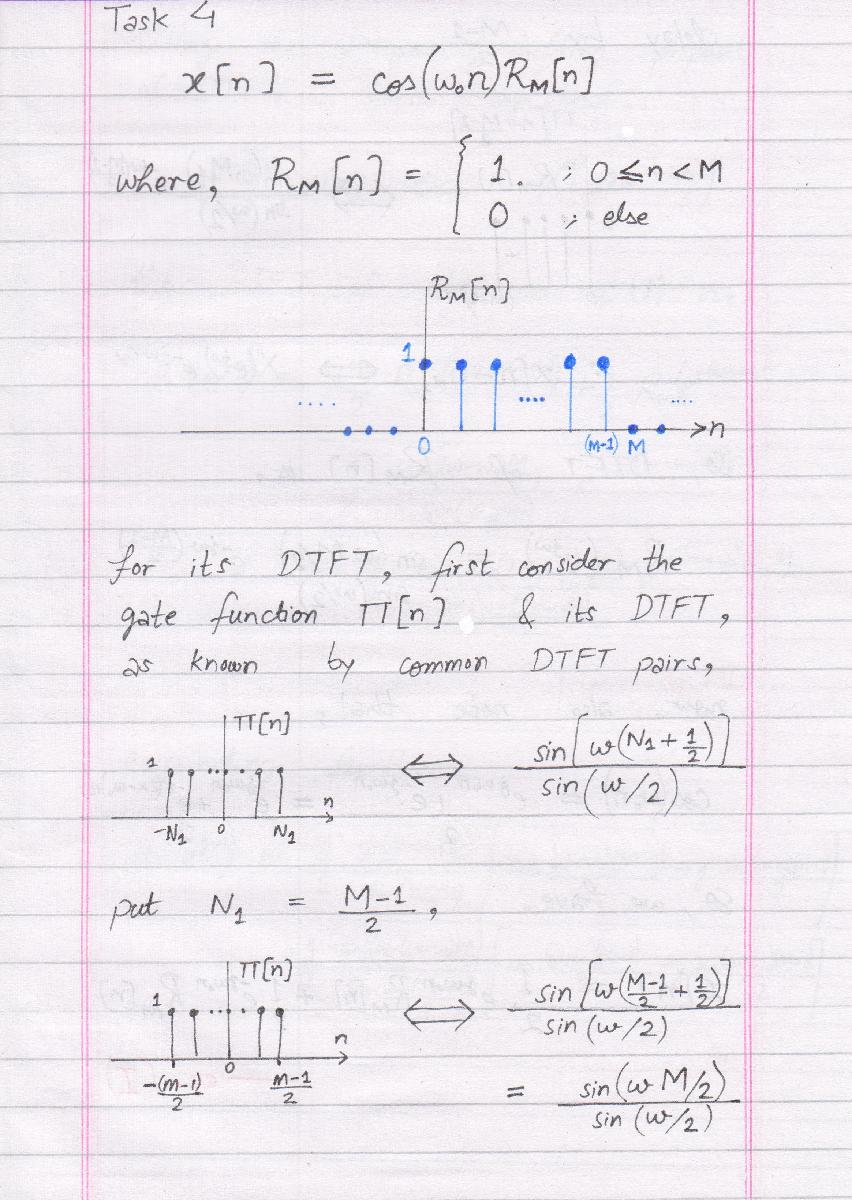

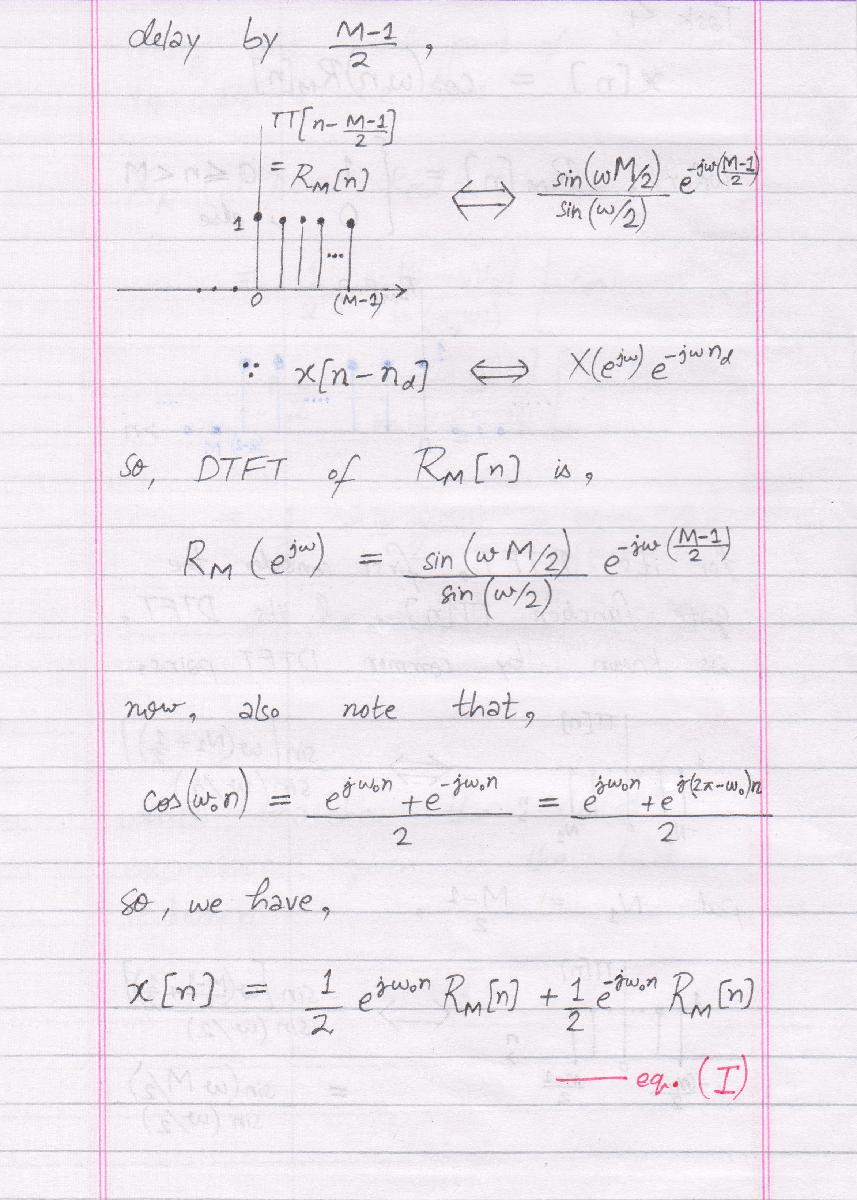

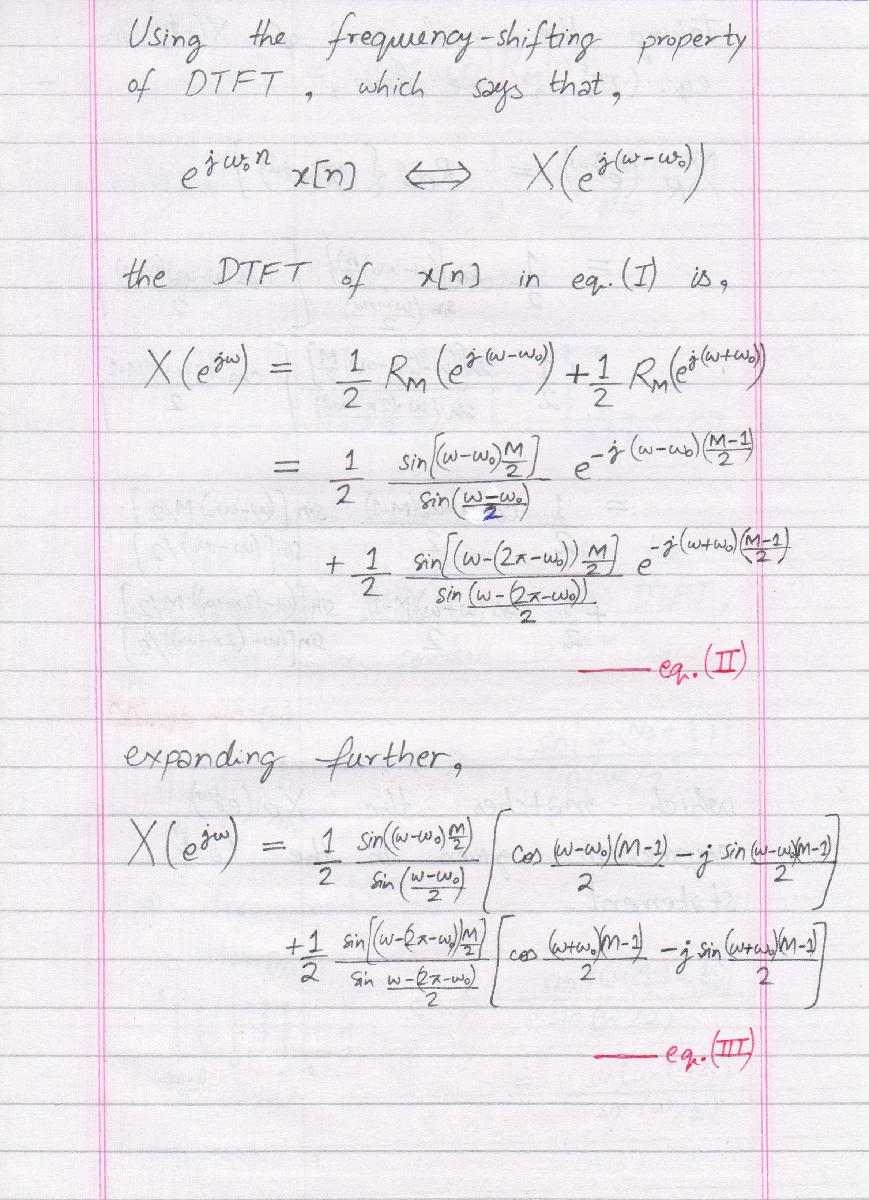

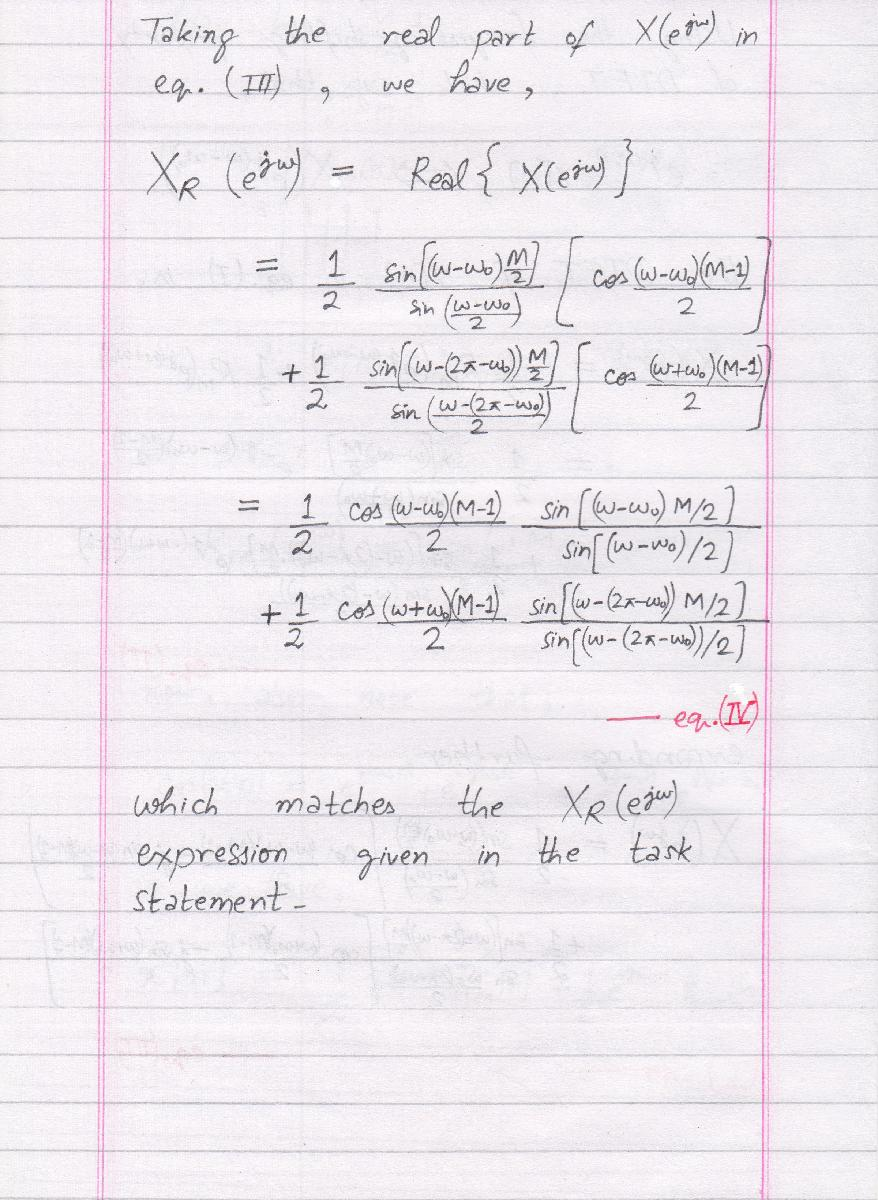

**Plotting **${\mathit{\mathbf{X}}}_{\mathit{\mathbf{R}}} \left({\mathit{\mathbf{e}}}^{\mathit{\mathbf{j}}\omega } \right)$** using MATLAB:**

Following code plots $X_R \left(e^{j\omega } \right)$ for the various provided $M$ values:

M = [5 15 25 100];                      % values of M for which to compute DTFT
w0 = pi/2;                              % given w0 value

w = -pi:0.01:pi;                        % frequency vector for computing DTFTs
XRw = cell(length(M), 1);               % cell-array to store DTFTs (real part) for each M

for i = 1:length(M)

    % define the rectangular pulse RM[n]
    n = 0:(M(i)-1);
    RM = ones(1, length(n));
    
    % define given x[n]
    x = cos(w0*n).*RM;
    
    % compute the DTFT of x[n] i.e. X(w), using matrix-mult. method
    Xw = x * exp(-1i * n' * w);
    
    % store the real part of DTFT i.e. XR(w)
    XRw{i} = real(Xw);
    
    % compare computed XR(w) with equation of XR(w) (given & derived in paperwork)
    XRw_eq = (1/2)*cos((w-w0)*(M(i)-1)/2).*sin((w-w0)*M(i)/2)./sin((w-w0)/2)...
             + (1/2)*cos((w+w0)*(M(i)-1)/2).*sin((w+w0)*M(i)/2)./sin((w+w0)/2);
    % message only displayed if results don't match
    if ~isequal(round(XRw{i}, 10), round(XRw_eq, 10))
        disp('Result Mismatch'); 
    end

end

% plot DTFT real part XR(w) for each M value
fig = figure; set(fig,'Units','normalized','Position',[0 0 1 1.6]);
sgtitle('X_R(e^{jw}) i.e. Real Part of X(e^{jw}) vs w');

for i = 1:4
    subplot(2, 2, i);
    plot(w, XRw{i});
    xlabel('w   (radians/sample)'); 
    ylabel(['X_R' ,'(e^{jw})']);
    ttl = {['[M = ', num2str(M(i)), ']']};
    if i > 2;  ttl = [{''}; ttl]; end; 
    title(ttl);
    setDTFTradialAxis(1);
end

Plots above show that $X_R \left(e^{j\omega } \right)$ has a sinc behaviour (as it has 2 sinc terms in its expression). These sincs have been shifted to $\pm 0\ldotp 5\pi$. Hence, when used as a (digital) filter, this system will let through the CT frequencies,


$$\Omega \;=\;\frac{\omega }{T}\;=\;\frac{\pm \;\pi /2}{2\pi /\Omega_S }\;=\;\pm \;\frac{\Omega_S }{4}$$


and a few ones around it. Here, $\Omega_S$ is considered to be the sampling frequency of signal passed through the DT system $X\left(e^{j\omega } \right)$.

As $M$ is increased, $X_R \left(e^{j\omega } \right)$ becomes more and more like sharp impulses at $\omega =\pm \;\pi /2$, and hence the frequencies other than $\pm \;\pi /2$ are more precisely eliminated.

## Task 5

**Statement:**

The in-built $\textrm{deconv}\left(\right)$ function is useful in dividing two causal sequences. Write a MATLAB function $\textrm{deconv}\_\mathrm{m}\left(\right)$ to divide two noncausal sequences, having the format: 


$$\textrm{function}\;\left\lbrack p,\;\textrm{np},\;r,\;\textrm{nr}\right\rbrack =\textrm{deconv}\_\mathrm{m}\left(b,\;\textrm{nb},\;a,\;\textrm{na}\right)$$


Check your function on the following operation: 


$$\frac{z^2 +z+1+z^{-1} +z^{-2} +z^{-3} }{z+2+z^{-1} }\;\;\;=\;\;\;\left(z-1+{2z}^{-1} -2z^{-2} \right)\;+\;\frac{3z^{-2} +3z^{-3} }{z+2+z^{-1} }$$


**Code (*****deconv_m.m*****):**

Code for the function $\textrm{deconv}\_\mathrm{m}\left(\right)$, that can be used to divide (de-convolve) two noncausal sequences, is given below.

% <function>
% modified deconvolution routine for noncausal sequences
%
% <syntax>
% [p, np, r, nr] = deconv_m(b, nb, a, na)
%
% <I/O>
% b = numerator polynomial of support nb1 <= n <= nb2,      nb = [nb1, nb2]
% a = denominator polynomial of support na1 <= n <= na2,    na = [na1, na2]
% p = polynomial part of support np1 <= n <= np2,           np = [np1, np2]
% r = remainder part of support nr1 <= n <= nr2,            nr = [nr1, nr2]

function [p, np, r, nr] = deconv_m(b, nb, a, na)

    % perform deconvolution using inbuilt MATLAB function
    [p, r] = deconv(b, a);

    % compute n-axis values for quotient p
    np_b = nb(1) - na(1);                   % beginning n value for p
    np_e = np_b + length(p) - 1;            % ending n value for p
    np = np_b:np_e;

    % compute n-axis values for remainder r
    nr_b = nb(1);                           % beginning n value for r
    nr_e = nr_b + length(r) - 1;            % ending n value for r
    nr = nr_b:nr_e;

end

**Testing **$\textrm{deconv}\_\mathbf{m}\left(\right)$** function on given operation:**

The code given below tests the above function $\textrm{deconv}\_\mathrm{m}\left(\right)$ using the z-domain expression provided in Task Statement, which can be treated as:


$$X_2 \left(z\right)\;\;\;=\;\;\;\frac{X_3 \left(z\right)}{X_1 \left(z\right)}\;\;\;=\;\;\;\frac{z^2 +z+1+z^{-1} +z^{-2} +z^{-3} }{z+2+z^{-1} }\;\;\;=\;\;\;\left(z-1+{2z}^{-1} -2z^{-2} \right)\;+\;\frac{3z^{-2} +3z^{-3} }{z+2+z^{-1} }$$


% z-inv of numerator (dividend) i.e. b[n] <==> X3(z)
b = [1 1 1 1 1 1];
nb = -2:3;

% z-inv of denominator (divisor) i.e. a[n] <==> X1(z)
a = [1 2 1];
na = -1:1;

% perform deconvolution on non-causal sequences (b[n] deconv a[n])
[p, np, r, nr] = deconv_m(b, nb, a, na)

% result in z-domain X2(z) = X3(z)/X1(z), using results p & r from deconv_m()
syms z;
X2 = (p*(z.^-np).') + (r*(z.^-nr).')/(a*(z.^-na).')

% compare against known answer
X2_expected = (z - 1 + 2*z^-1 - 2*z^-2) + (3*z^-2 + 3*z^-3) / (z + 2 + z^-1);
if isequal(X2, X2_expected)
    disp(['The result of the deconv_m() function matches with the ',... 
        'given answer for deconvolution (or z-domain division).'])
end

The expression obtained from the results of $\textrm{deconv}\_\mathrm{m}\left(\right)$, given above by "$\textrm{X2}$", is the same as R.H.S. of $X_2 \left(z\right)$ expression given at the top.

## Task 6

**Statement:**

A stable system has four zeros and four poles as given below. 


$$\textrm{Zeros}:\;\pm 1,\;\pm \textrm{j1}$$
               
$$\textrm{Poles}:\;\pm 0\ldotp 9,\;\pm \textrm{j0}\ldotp 9$$


It is also known that the frequency response function $H\left(e^{j\omega } \right)$ evaluated at $\omega =\pi /4$ is equal to $1$, that is, 


$$H\left(e^{\;j\;\;\pi /4} \right)\;=\;1$$


**Question (1):    **Determine the system function $H\left(z\right)$, and indicate its region of convergence ($\textrm{ROC}$).

**Question (2):    **Determine the difference equation representation.

**Question (3):    **Determine the steady-state response $y_{\textrm{ss}} \left\lbrack n\right\rbrack$ if the input is $x\left\lbrack n\right\rbrack =\cos \left(\pi \;n/4\right)\;u\left\lbrack n\right\rbrack$.

**Question (4):    **Determine the transient response $y_{\textrm{tr}} \left\lbrack n\right\rbrack$ if the input is $x\left\lbrack n\right\rbrack =\cos \left(\pi \;n/4\right)\;u\left\lbrack n\right\rbrack$.

**Answers (1-4):**

The work done on paper, i.e. answers to Q1, Q2, Q3 and Q4 above, starts from the next page.

*The work done on paper starts from the next page.*

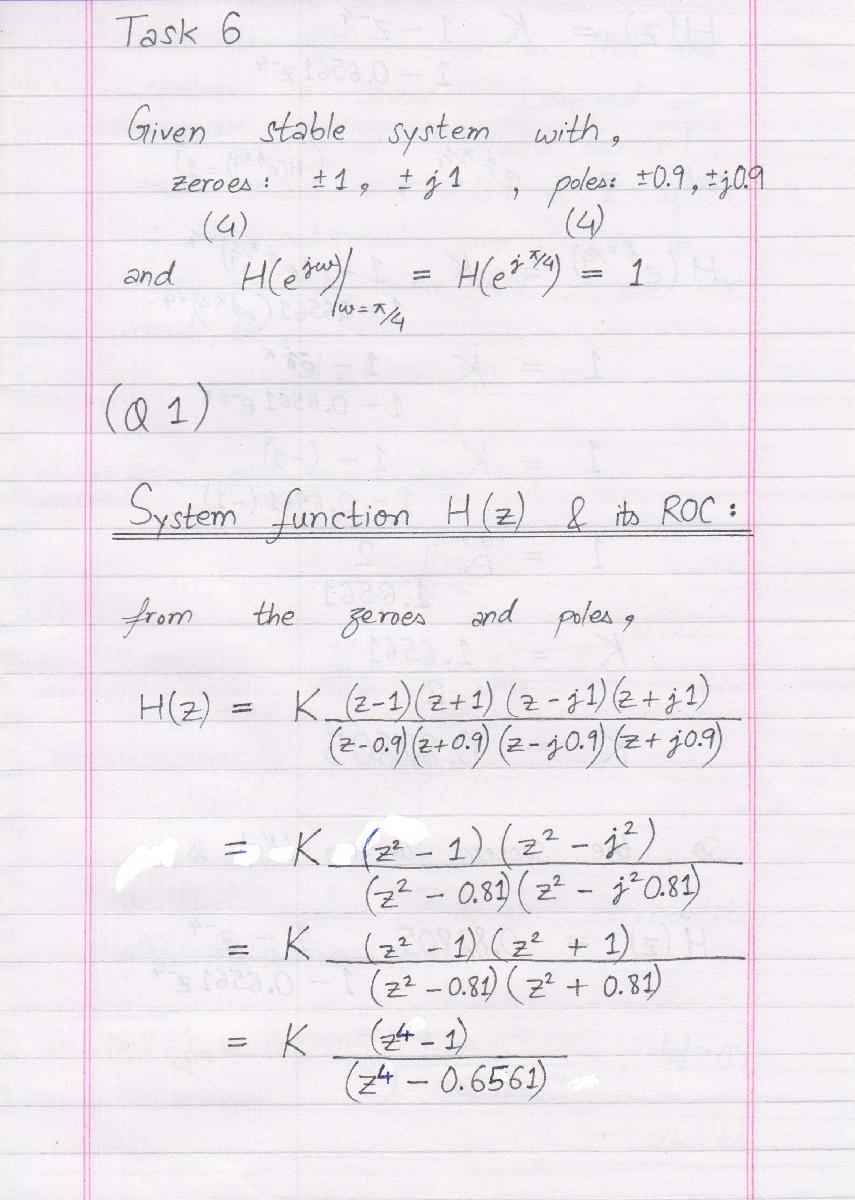

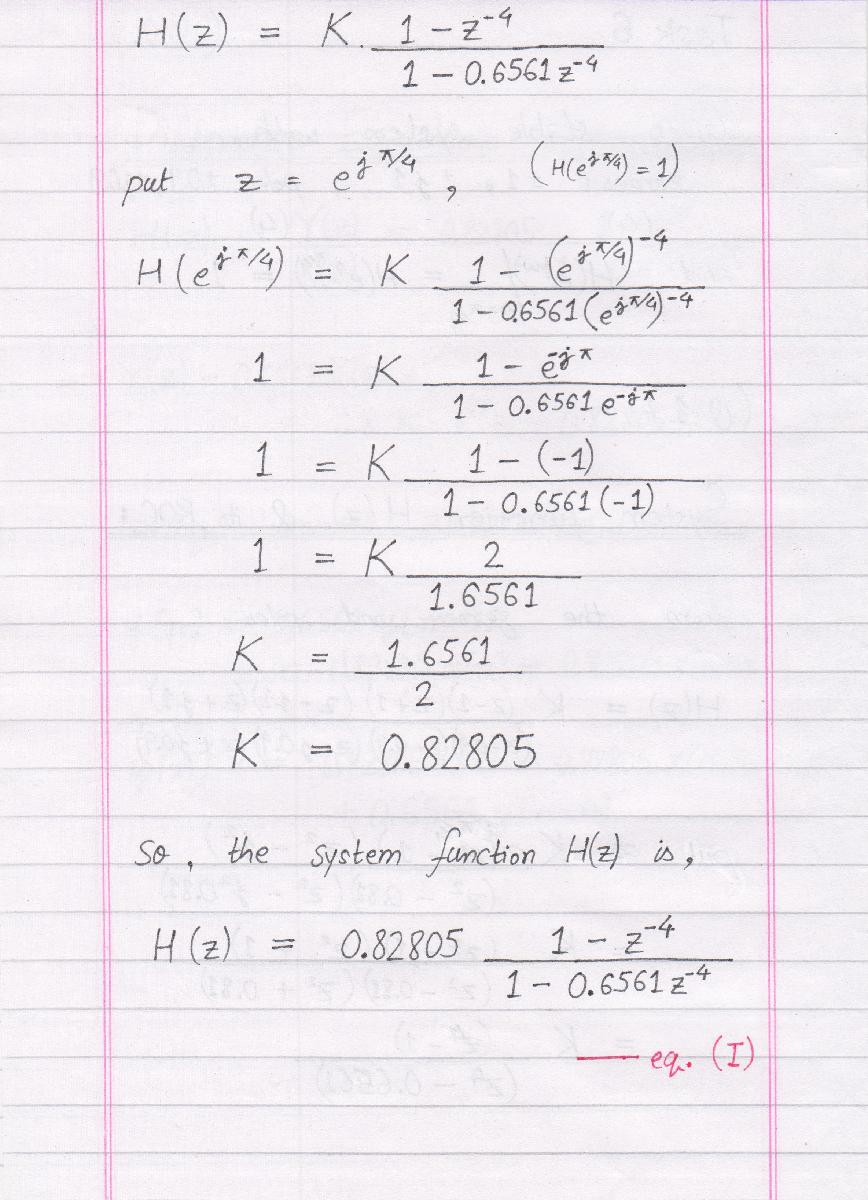

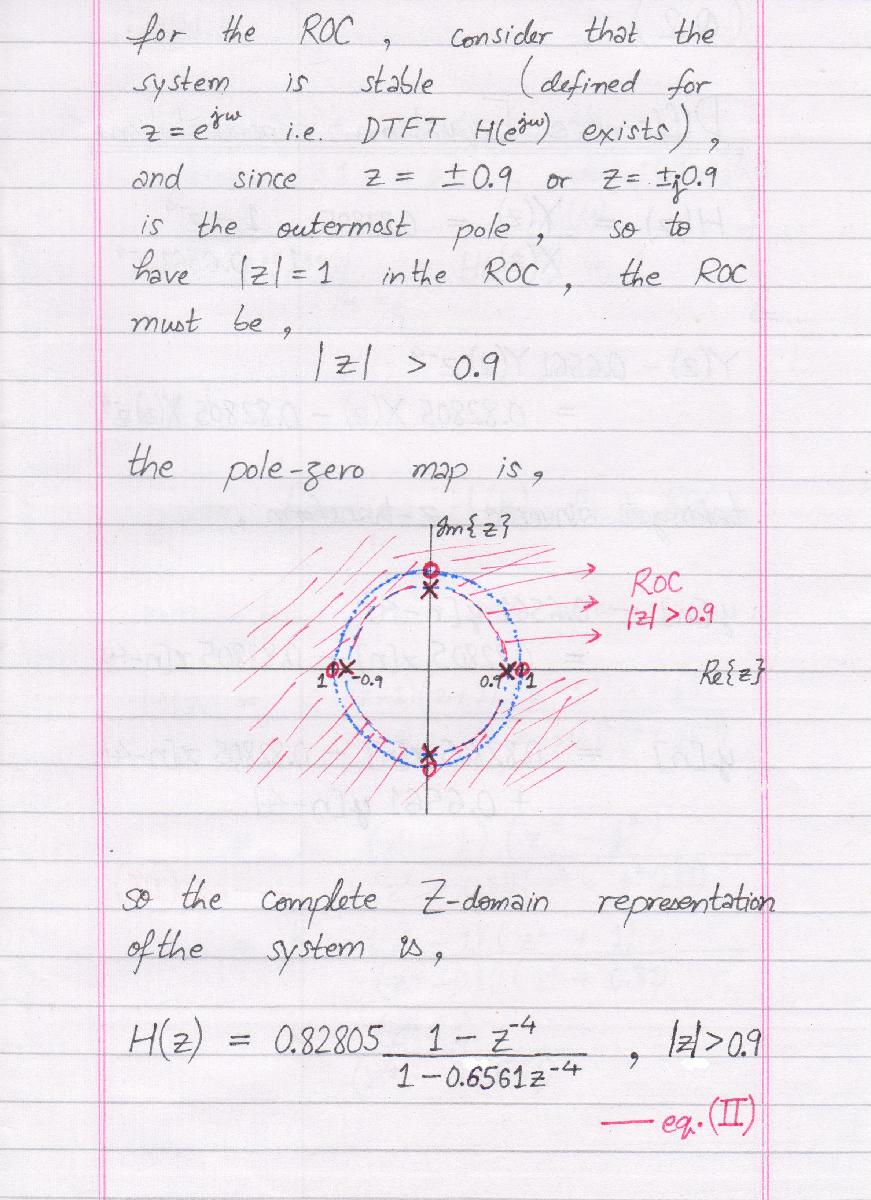

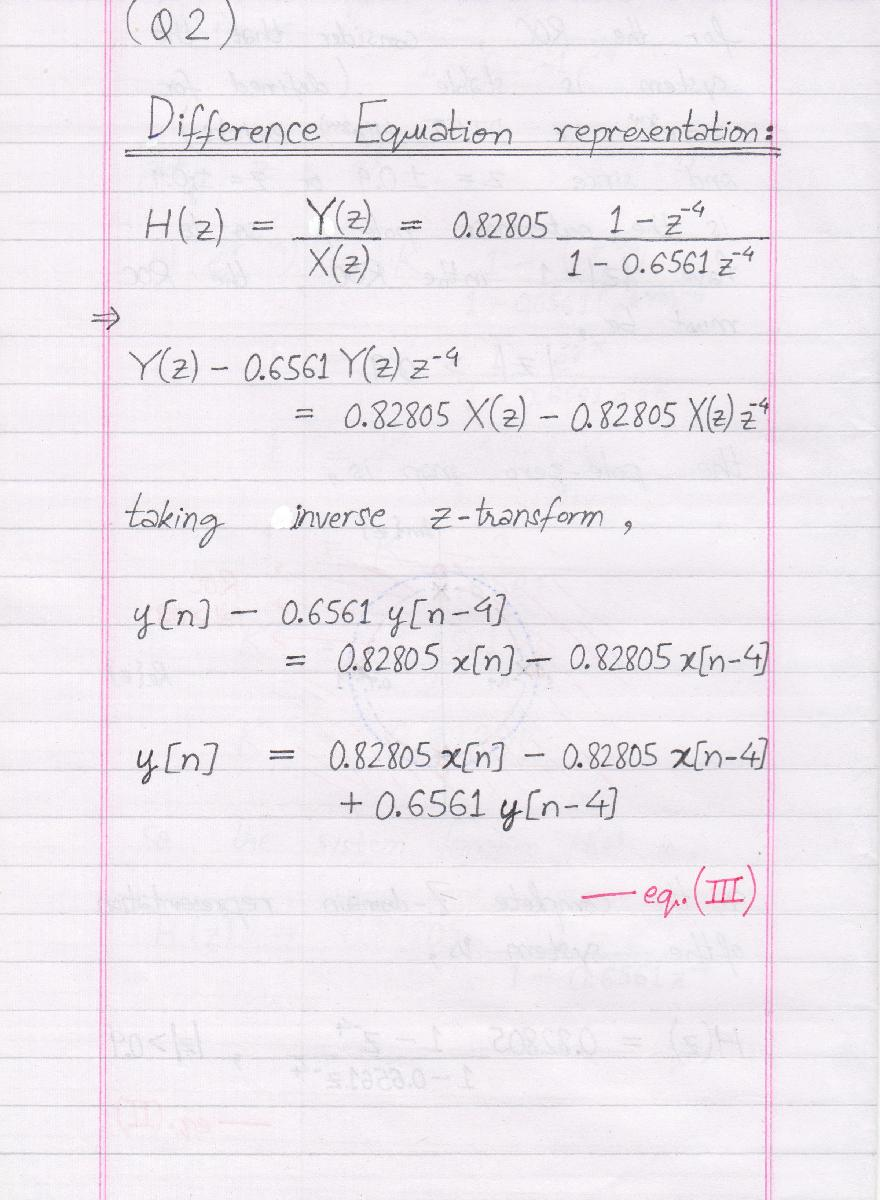

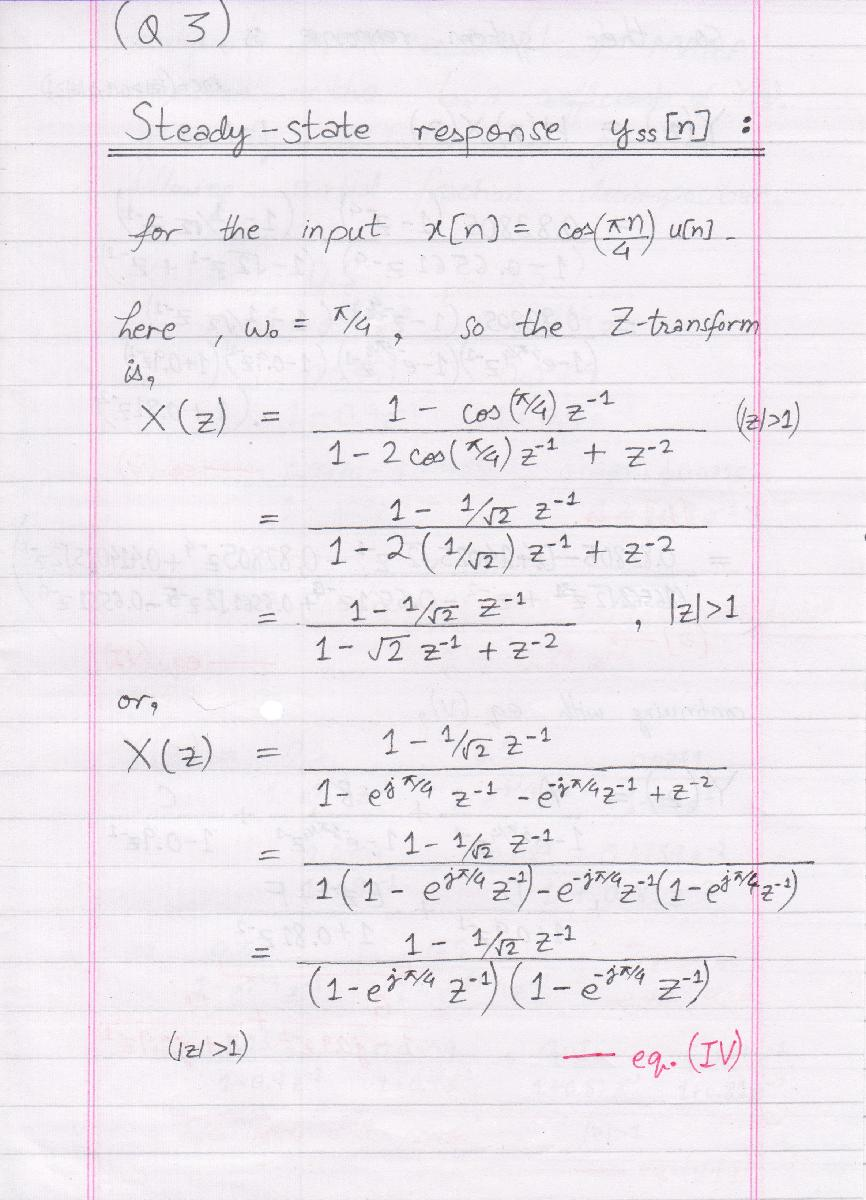

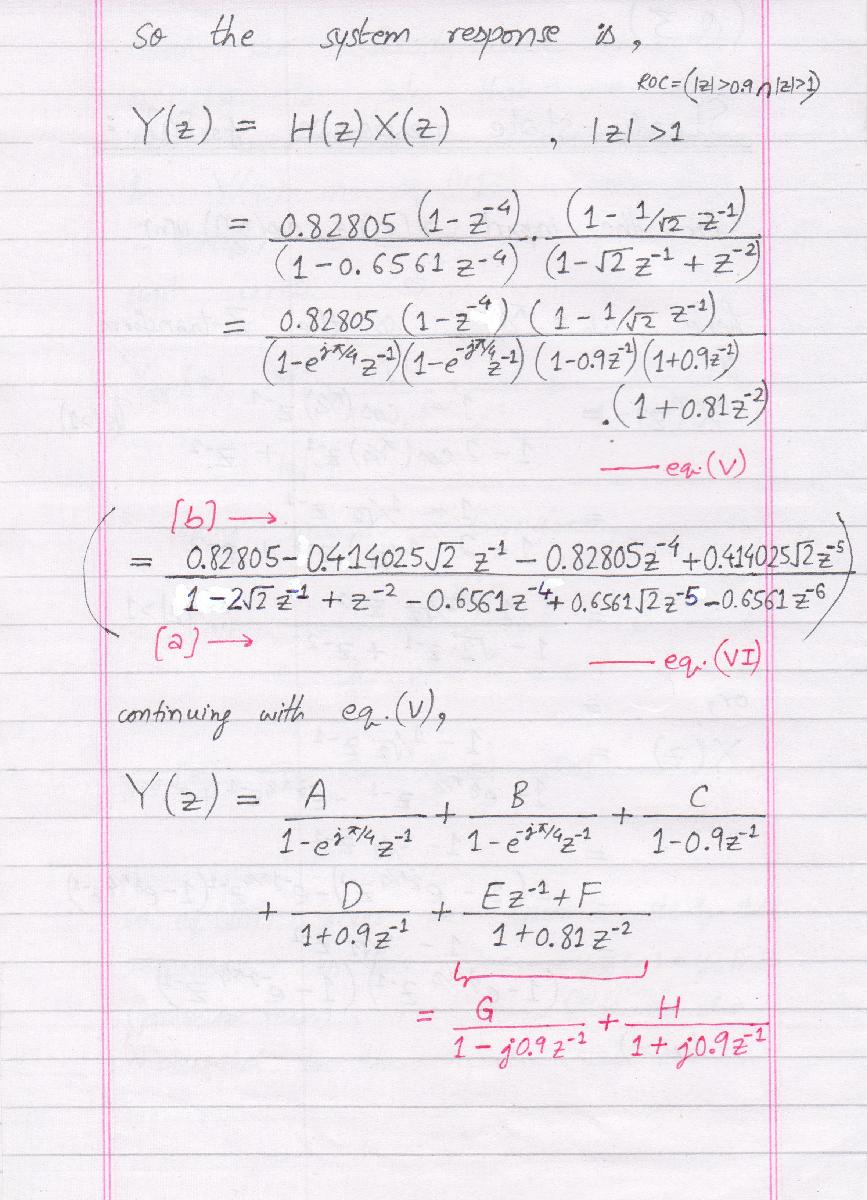

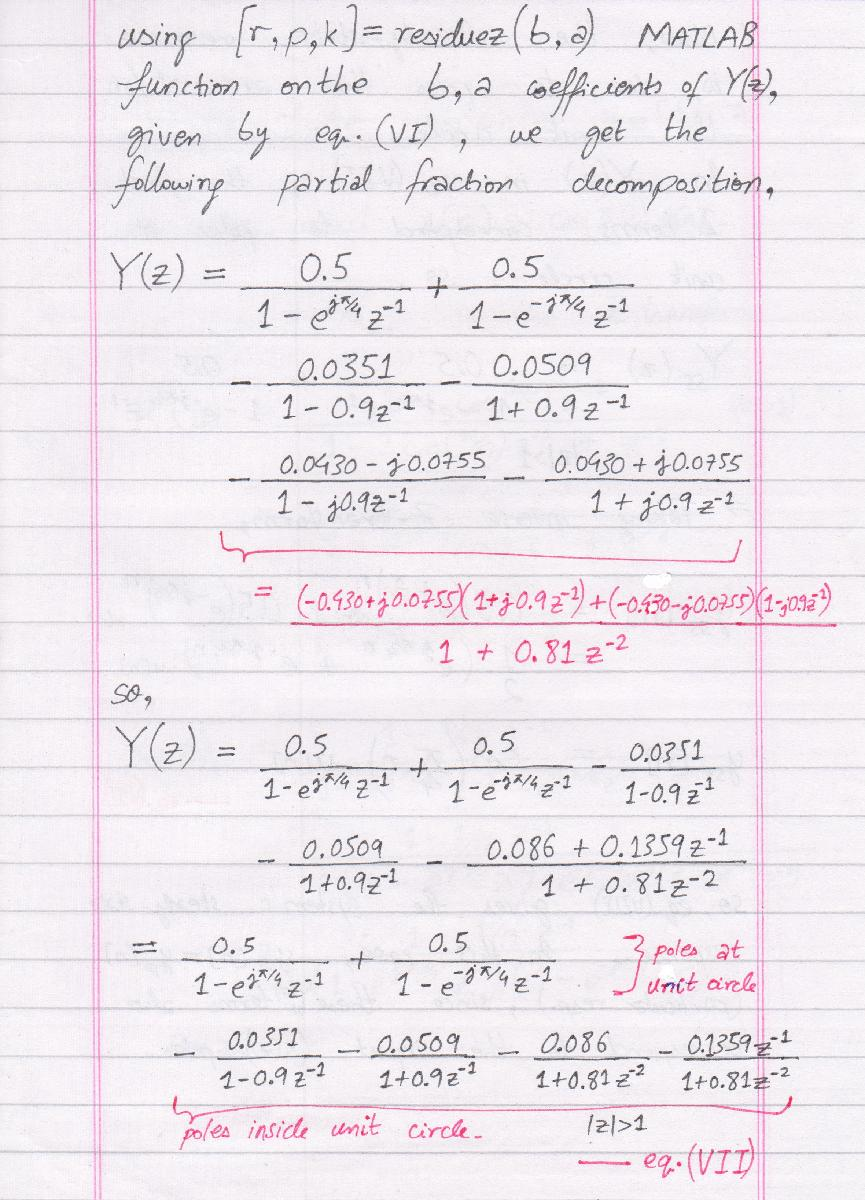

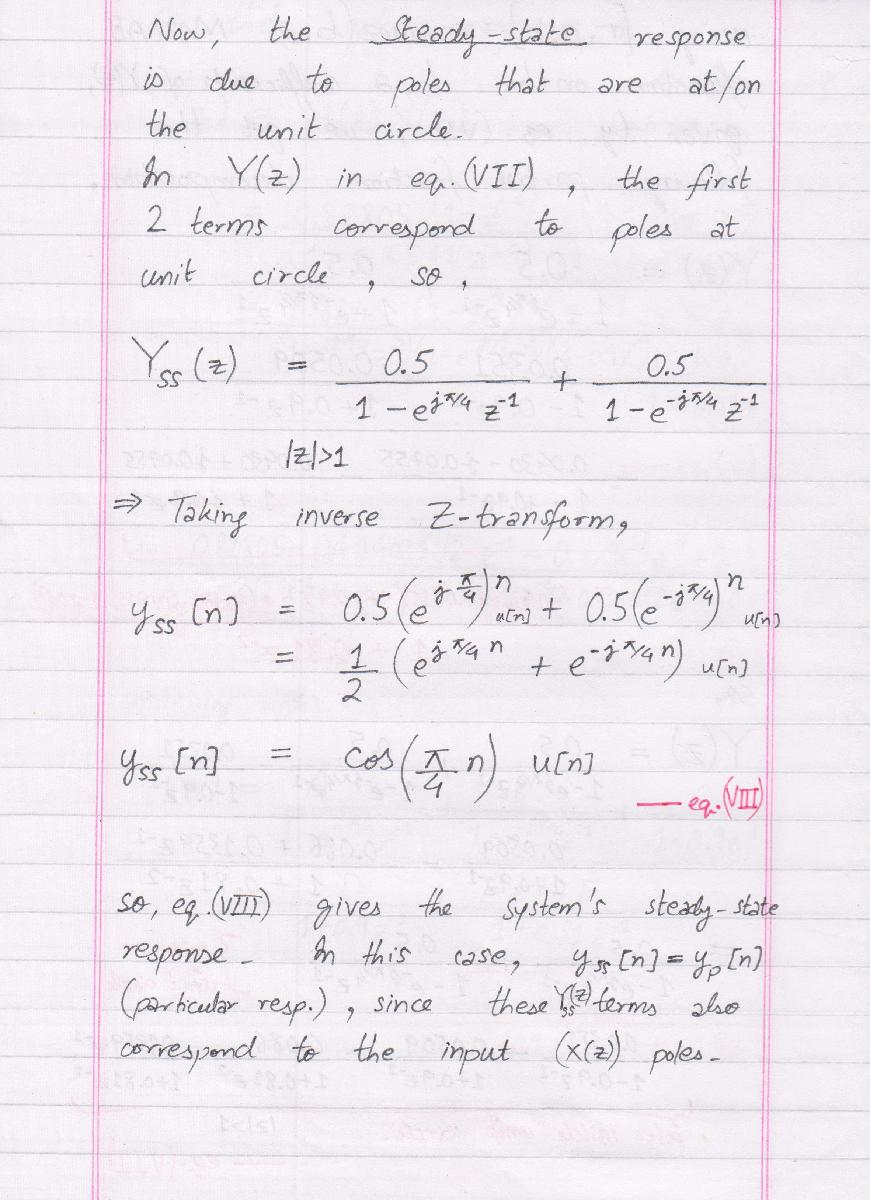

So the answers to Q1-4 are:

**(Q1)**


$$H\left(z\right)\;=\;0\ldotp 82805\frac{1-z^{-4} }{1-0\ldotp 6561z^{-4} }$$
        
$$\textrm{ROC}\;=\;|z|>0\ldotp 9$$


**(Q2)**


$$y\left\lbrack n\right\rbrack \;=\;0\ldotp 82805\;x\left\lbrack n\right\rbrack -0\ldotp 82805\;x\left\lbrack n-4\right\rbrack +0\ldotp 6561\;y\left\lbrack n-4\right\rbrack$$


**(Q3)**


$$Y\left(z\right)=\;\frac{0\ldotp 5}{1-e^{j\pi /4} z^{-1} }+\frac{0\ldotp 5}{1-e^{-j\pi /4} z^{-1} }-\frac{0\ldotp 0351}{1-0\ldotp 9z^{-1} }-\frac{0\ldotp 0509}{1+0\ldotp 9z^{-1} }-\frac{0\ldotp 086}{1+0\ldotp 81z^{-2} }-\frac{0\ldotp 1359z^{-1} }{1+0\ldotp 81z^{-2} }$$
        
$$\textrm{ROC}\;=\;|z|>1$$
        


$$y_{\textrm{ss}} \left\lbrack n\right\rbrack \;=\;\cos \left(\frac{\pi }{4}n\right)\;u\left\lbrack n\right\rbrack$$


**(Q4)**


$$y_{\textrm{tr}} \left\lbrack n\right\rbrack \;=\;-0\ldotp 0351{\left(0\ldotp 9\right)}^{n\;} u\left\lbrack n\right\rbrack -0\ldotp 0509{\left(-0\ldotp 9\right)}^n \;u\left\lbrack n\right\rbrack -0\ldotp 086{\left(0\ldotp 9\right)}^n \;\cos \left(\frac{\pi }{2}n\right)\;u\left\lbrack n\right\rbrack -0\ldotp 151{\left(0\ldotp 9\right)}^n \;\sin \left(\frac{\pi }{2}n\right)\;u\left\lbrack n\right\rbrack$$


Some parts of the computation, such as partial fraction decomposition and conformation of other results, were done in MATLAB with the following code. 

*Note:*  This code uses a modified version of the $\textrm{get}\_\textrm{zsys}\_\textrm{coeffs}\left(\right)$ function implemented in Assignment 4.

% (Q1)
% ------------
% determining complete H(z)

zeros = [1 -1 1i -1i];                      % zeros in H(z)
poles = [0.9 -0.9 1i*0.9 -1i*0.9];          % poles in H(z)

% define H(z) using poles, zeros, and coefficient k
syms z k;
Hz = k * prod(z-zeros) / prod(z-poles);

% determine K, given H(e^jπ/4) = 1
Hw = subs(Hz, z, exp(1i*pi/4)) == 1;
K = vpa(solve(Hw, k))

% so complete H(z) is,
Hz = subs(Hz, k, K)
Hz = vpa(expand(Hz))

% pole-zero map
fig = figure;
zplane(zeros.', poles.');
title('Pole-Zero Map of given system');

% (Q3 & Q4)
% ------------
% determining the partial fraction form, and the inverse, of Y(z)

% define Y(z) = H(z)X(z) in terms of z^-1 
% using paperwork equation on Page 28 (top)
syms z;
N = 0.82805*(1-z^-4)*(1-1/sqrt(2)*z^-1);            % numerator of Y(z)
D = ((1-0.6561*z^-4)*(1-sqrt(2)*z^-1+z^-2));        % denominator of Y(z)
Yz = N / D;
Yz = expand(Yz);

% find the CCDE coefficients of Y(z)
[b, a] = get_zsys_coeffs(N, D);

% check if the coefficients are correct against factorized Y(z)
Yz2 = sum(b.*z.^-(0:(length(b)-1)))/sum(a.*z.^-(0:(length(a)-1)));
Yz2 = expand(Yz2);
isequal(Yz, Yz2)

% determine the partial fraction form of Y(z)
[r, p, k] = residuez(double(b), double(a))

% display partial fraction sum symbolically
p = round(p, 4); r = round(r, 4); k = round(k, 4);
Yz = sum(r./(1-p*z^-1));
if ~isempty(k)
    Yz = Yz + sum(k.*z.^-(0:(length(k)-1)));
end
Yz = vpa(Yz, 5)

The expression for $H\left(z\right)$ given by "Hz" in the code matches the expression derived on paper (Page 25, eq. (II)). The partial fraction decomposition of $Y\left(z\right)$ computed above ("Yz") has been used in paperwork (Page 29, eq. (VII)) to solve Q3 & Q4.